# Building Regression Models

## 1. Linear Regression Models

Which of these is NOT a linear regression model? (5, 6)


$$\begin{array}{l}
1\ldotp \;y=a+\textrm{bx}+cx^2 \\
2\ldotp \;y=ax_1 +{\textrm{bx}}_2 +{\textrm{cx}}_3 \\
3\ldotp \;y=ax_1 x_2 +bx_2 x_3 +cx_1 x_3 \\
4\ldotp \;y=a+\textrm{bsin}\left(x_1 \right)+\textrm{csin}\left(x_2 \right)\\
5\ldotp \;y=a+\textrm{bsin}\left(\textrm{cx}\right)\\
6\ldotp \;y=a+\textrm{bx}+x^c 
\end{array}$$


*Note: Models with products of predictor variables may still be linear in the fit coefficients. However, products of coefficients are not considered linear. Also, taking the power of a predictor to the power of a coefficient will be nonlinear.*

### Course Example: Fuel Economy

Load fuel economy data and view the relationships between the numeric predictors and response.

load carEcon
carData

carData = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    PRP    FuelType    City_Highway    Valves_Cyl    FuelEcon
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ___    ________    ____________    __________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         city              4          3.5318 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           29.1        N     31        61         highway           4          3.6187 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         highway           4          3.6299 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           2

### 1.1. Fit a single predictor linear model of fuel economy

Fit a single predictor linear model

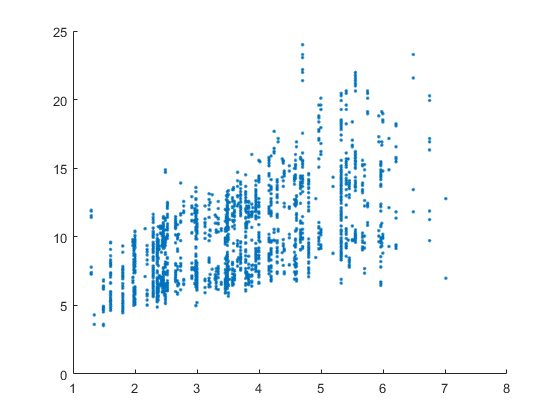

figure
scatter(carData.EngDisp, carData.FuelEcon,'.')

mdl = fitlm(carTrain(:,{'EngDisp','FuelEcon'}))

mdl = 선형 회귀 모델:
    FuelEcon ~ 1 + EngDisp

추정된 계수:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)     3.9506       0.2075    19.039     5.4916e-73
    EngDisp         1.6591     0.054062    30.689    6.2992e-163


관측값 개수: 1597, 오차 자유도: 1595
RMS 오차: 2.67
결정계수: 0.371, 수정된 결정계수: 0.371
상수 모델에 대한 F-통계량: 942, p-값 = 6.3e-163

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

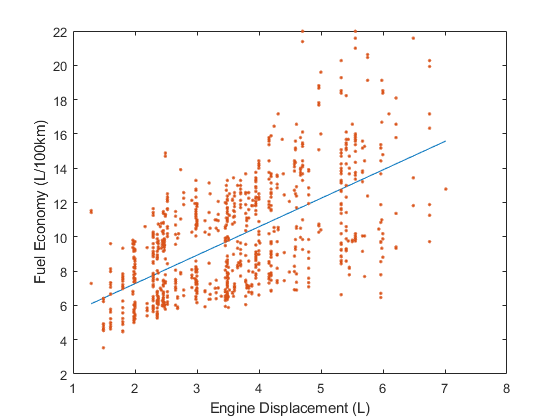

econPred = predict(mdl,carTest.EngDisp);

% Fuel economy according to engine displacement
figure
plot(carTest.EngDisp,econPred)
hold on
scatter(carTest.EngDisp, carTest.FuelEcon,'.')
xlabel("Engine Displacement (L)")
ylabel("Fuel Economy (L/100km)")

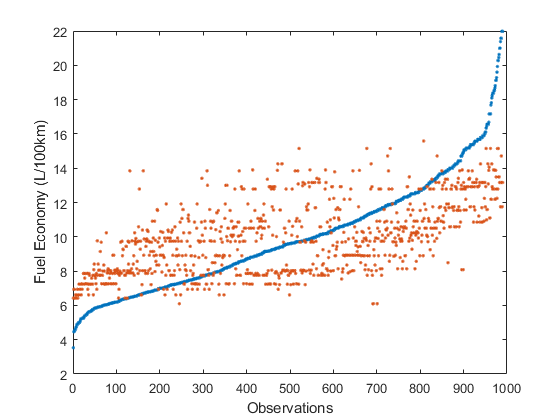

% Fuel economy according to observations
figure
plot(carTest.FuelEcon,'.')
hold on
plot(econPred,'.')
xlabel("Observations")
ylabel("Fuel Economy (L/100km)")

Plot distribution of errors

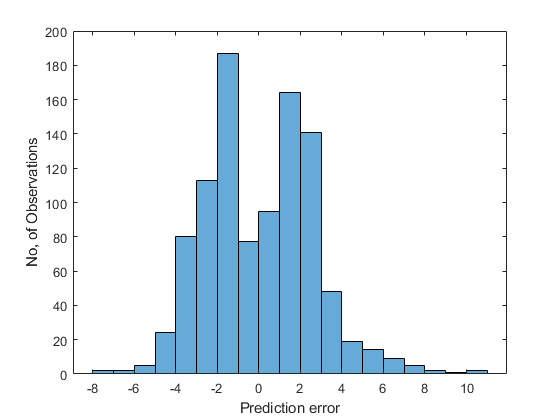

figure
err = carTest.FuelEcon - econPred; 
histogram(err)
xlabel('Prediction error')
ylabel('No, of Observations')

MSE = mean(err.^2)

MSE = 6.7805

Plot ditribution of percentage errors

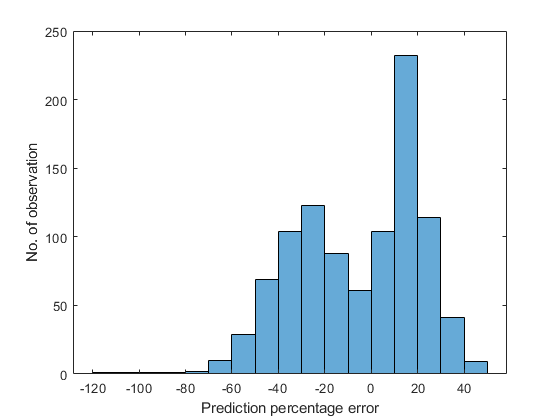

figure
percErr = 100 * err./carTest.FuelEcon;
histogram(percErr)
xlabel('Prediction percentage error')
ylabel('No. of observation')

MAPE=mean(abs(percErr))

MAPE = 23.1000

### 1.2. Fit a two-predictor linear model of fuel economy

NOTE!! When you use `fitlm`, use a table data type rather than an array data type. Because it is much easier to use `'modelspec'` option with a table data type.

For input format in `'modelspec'`, see *Wilkinson-Rogers* notation.

doc wilkinson notation

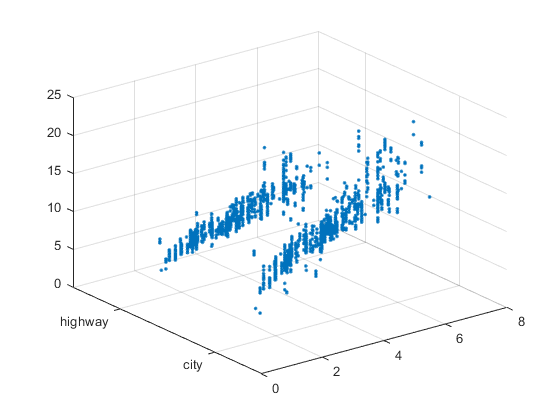

figure
scatter3(carData.EngDisp,carData.City_Highway,carData.FuelEcon,'.')

mdl = fitlm(carTrain(:,{'EngDisp','City_Highway','FuelEcon'}))

mdl = 선형 회귀 모델:
    FuelEcon ~ 1 + EngDisp + City_Highway

추정된 계수:
                            Estimate       SE        tStat       pValue   
                            ________    ________    _______    ___________

    (Intercept)              6.0877      0.12745     47.765    7.9475e-310
    EngDisp                  1.6694     0.031644     52.754              0
    City_Highway_highway    -4.3246     0.078159    -55.331              0


관측값 개수: 1597, 오차 자유도: 1594
RMS 오차: 1.56
결정계수: 0.785, 수정된 결정계수: 0.784
상수 모델에 대한 F-통계량: 2.91e+03, p-값 = 0

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

econPred = predict(mdl,carTest(:,{'EngDisp','City_Highway'}))

econPred =     8.5771
    4.7723
    4.7723
    4.2525
    4.2525
    4.4440
    4.2525
    4.4440
    4.2525
    4.7723




% Plot against observation number
figure
subplot(2,2,1)
plot(carTest.FuelEcon,'.')
hold on
plot(econPred,'.')
title('linear (disp + city/highway)')
xlabel('Obsercations')
ylabel('Fuel economy')

% Plot predicted and actual against each other
subplot(2,2,2)
scatter(carTest.FuelEcon,econPred,'.')

% Add 45-degree line
xlimt=xlim;
hold on
plot(xlimt,xlimt,'k')
title('linear (disp + city/highway)')
xlabel('Actual fuel economy')
ylabel('Predicted fuel economy')

% Distribution of errors
subplot(2,2,3)
err = carTest.FuelEcon - econPred;
MSE= mean(err.^2)

MSE = 2.2971

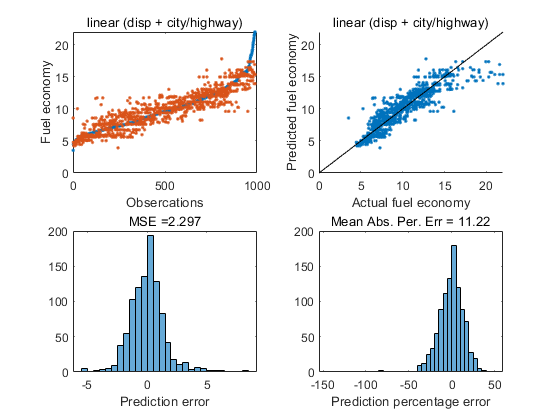

histogram(err)
xlabel('Prediction error')
title(['MSE =',num2str(MSE,4)])

% Distribution of percentage errors
subplot(2,2,4)
percErr = 100 * err./carTest.FuelEcon;
MAPE=mean(abs(percErr));
histogram(percErr)
xlabel('Prediction percentage error')
title(['Mean Abs. Per. Err = ',num2str(MAPE,4)])

### 1.3. Fit a multivariate linear model of fuel economy

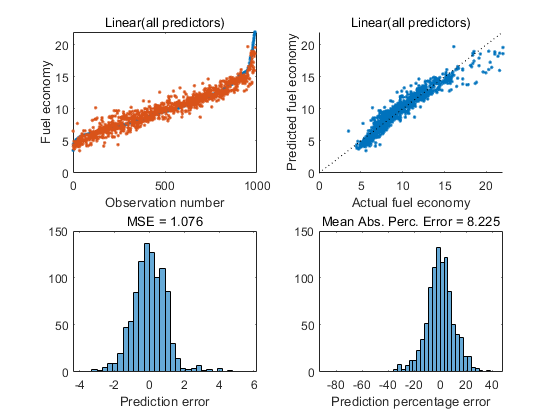

mdl=fitlm(carTrain);
econPred=predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'Linear(all predictors)')

Specify the 'RobustOpts' option to reduce the influence of outliers

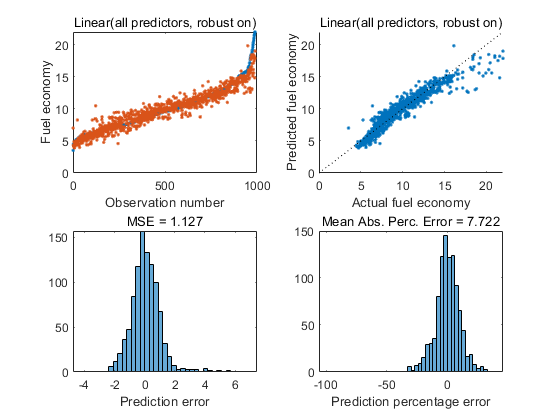

mdl = fitlm(carTrain,'RobustOpts','cauchy');
econPred=predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'Linear(all predictors, robust on)')

## 2. Stepwise Fitting

'Stepwise Fitting' is similar with 'Sequential Feature Selection' but provides a simpler interface.

- Sequential Feature Selection : Data + evaluation function

- Stepwise fitting: Data + Criterion( sse(default), aic, bic, rsquared, adjrsquared )

Perform a stepwise linear fit of fuel economy

mdl = stepwiselm(carTrain);

1. City_Highway, FStat = 1103.1943, pValue = 2.6005394e-184 추가
2. EngDisp, FStat = 2783.0129, pValue = 0 추가
3. FuelType, FStat = 84.721, pValue = 8.03591e-105 추가
4. EngDisp:City_Highway, FStat = 347.5023, pValue = 2.768531e-70 추가
5. Drive, FStat = 136.4937, pValue = 2.038924e-55 추가
6. Transmission, FStat = 14.0464, pValue = 4.80023e-36 추가
7. Weight, FStat = 277.8036, pValue = 1.508394e-57 추가
8. Valves_Cyl, FStat = 123.5276, pValue = 1.123981e-27 추가
9. Transmission:Valves_Cyl, FStat = 10.6438, pValue = 1.45971e-20 추가
10. Transmission:Weight, FStat = 8.2467, pValue = 2.3888e-18 추가
11. AC, FStat = 75.332, pValue = 9.95502e-18 추가
12. City_Highway:Valves_Cyl, FStat = 61.4004, pValue = 8.62951e-15 추가
13. FuelType:City_Highway, FStat = 15.0735, pValue = 1.78455e-14 추가
14. Drive:Valves_Cyl, FStat = 32.6624, pValue = 1.28641e-14 추가
15. RatedHP, FStat = 77.7732, pValue = 3.08367e-18 추가
16. Comp, FStat = 70.5003, pValue = 1.03598e-16 추가
17. Transmission:City_Highway, FStat = 7.0895, pValue = 3.20

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

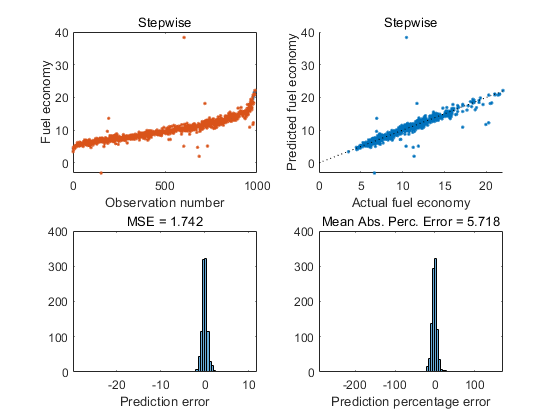

econPred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'Stepwise')

Change criterion and limit to linear models

mdl = stepwiselm(carTrain,'Criterion','aic','Upper','interactions')

1. City_Highway, AIC = 7569.9708 추가
2. EngDisp, AIC = 5958.8092 추가
3. FuelType, AIC = 5465.7601 추가
4. EngDisp:City_Highway, AIC = 5151.3658 추가
5. Drive, AIC = 4901.4393 추가
6. Transmission, AIC = 4719.5279 추가
7. Weight, AIC = 4460.8817 추가
8. Valves_Cyl, AIC = 4341.6305 추가
9. Transmission:Valves_Cyl, AIC = 4247.4859 추가
10. Transmission:Weight, AIC = 4156.0222 추가
11. AC, AIC = 4081.6557 추가
12. Transmission:City_Highway, AIC = 4016.3133 추가
13. FuelType:City_Highway, AIC = 3947.9985 추가
14. Drive:Valves_Cyl, AIC = 3881.5101 추가
15. RatedHP, AIC = 3798.1908 추가
16. Comp, AIC = 3726.0015 추가
17. RatedHP:Transmission, AIC = 3665.0781 추가
18. City_Highway:Valves_Cyl, AIC = 3605.0895 추가
19. Car_Truck, AIC = 3561.0914 추가
20. EVSpeedRatio, AIC = 3512.0349 추가
21. RatedHP:Valves_Cyl, AIC = 3472.8457 추가
22. RatedHP:Weight, AIC = 3414.1071 추가
23. Car_Truck:EngDisp, AIC = 3366.4604 추가
24. Drive:FuelType, AIC = 3339.9788 추가
25. EngDisp:RatedHP, AIC = 3318.0209 추가
26. RatedHP:EVSpeedRatio, AIC = 3283.4268 추가


mdl = 선형 회귀 모델:
    FuelEcon ~ 1 + Car_Truck*EngDisp + Car_Truck*RatedHP + Car_Truck*AxleRatio + Car_Truck*AC + Car_Truck*City_Highway + Car_Truck*Valves_Cyl + EngDisp*RatedHP + EngDisp*Transmission + EngDisp*EVSpeedRatio + EngDisp*AC + EngDisp*FuelType + EngDisp*Valves_Cyl + RatedHP*Transmission + RatedHP*Weight + RatedHP*Comp + RatedHP*AxleRatio + RatedHP*EVSpeedRatio + RatedHP*City_Highway + RatedHP*Valves_Cyl + Transmission*Weight + Transmission*AxleRatio + Transmission*EVSpeedRatio + Transmission*AC + Transmission*City_Highway + Drive*EVSpeedRatio + Drive*FuelType + Drive*Valves_Cyl + Weight*PRP + Weight*City_Highway + Weight*Valves_Cyl + Comp*AxleRatio + Comp*PRP + Comp*FuelType + Comp*City_Highway + Comp*Valves_Cyl + AxleRatio*EVSpeedRatio + AxleRatio*Valves_Cyl + EVSpeedRatio*AC + EVSpeedRatio*City_Highway + AC*PRP + AC*City_Highway + PRP*Valves_Cyl + FuelType*City_Highway + City_Highway*Valves_Cyl

추정된 계수:
                                             Estimate          SE      

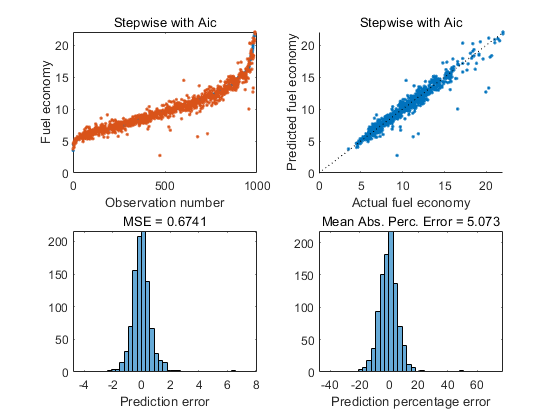

econPred = predict(mdl, carTest);
evaluatefit(carTest.FuelEcon,econPred,'Stepwise with Aic')

You can also use Sequential Feature Selection which provides a better result but be careful of running this section because it takes long time.

% rng(1234)
% part = cvpartition(carData.FuelEcon,'KFold',10);
% [carDataNum, carDataNum_names] = cattable2mat(carData);

Sequential feature selection on a Multiclass SVM.

% rng(1234)
% tokeep_nb = sequentialfs(@errorECOC,carDataNum,carData.FuelEcon,'cv',part)
% vars(tokeep_nb)

Callback function: errorECOC function returns the number of inaccurate predictions for `ytest` by a multiclass SVM classifier.

% function error = errorECOC(Xtrain,ytrain,Xtest,ytest)
% mdlnb = fitcecoc(Xtrain,ytrain);
% ypred = predict(mdlnb,Xtest);
% error = nnz(ypred ~= ytest);
% end